
clear;

csvFolderName = "trekking";
clockTimeLimit = 30; % 体験時間 (s)
period = 3; % 歩行周期 (s)

tiltBackwardTimeRate = 4;
tiltForwardTimeRate = 6;

liftLength = 37.5; % 椅子 リフト長 単位 (mm)
pedalLength = 40; % ペダル長 単位 (mm)
seatSlideForwardLength = 100; % 椅子 スライド長 単位 (mm)
seatSlideBackwardLength = 50; % 椅子 スライド長 単位 (mm)
extendLength = 125; % 伸縮長 単位 (mm)
stockSlideForwardLength = 187.5; % ストック スライド前方向長 単位 (mm)
stockSlideBackwardLength = 125; % ストック スライド後方向長 単位 (mm)
tiltBackwardDeg = 5; % ストック 後傾角度 (deg)
tiltForwardDeg = -12.5; % ストック 前傾角度 (deg)

stopTime = clockTimeLimit;
stopTable = table(stopTime);
writetable(stopTable, csvFolderName + '\' + "stop.csv");

椅子 リフト

L = liftLength; % スライド長 単位 (mm)
startClockTime = period/2; % 開始時刻 (s)
clockTimeU = 0; % 単位 (s)
clockTimeD = period/2*2/5; % 単位 (s)
deltaTimeU = period/2*2/5; % 単位 (s)
deltaTimeD = period/2*2/5; % 単位 (s)
positionU = L; % 単位 (mm)
positionD = 0; % 単位 (mm)

clockTimeUList = (startClockTime + clockTimeU):period/2:clockTimeLimit; % 単位 (s)
clockTimeDList = (startClockTime + clockTimeD):period/2:clockTimeLimit; % 単位 (s)
clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
tmp = [clockTimeUList; clockTimeDList];
clockTime = tmp(:);
deltaTimeUList = deltaTimeU + 0*clockTimeUList;
deltaTimeDList = deltaTimeD + 0*clockTimeDList;
tmp = [deltaTimeUList; deltaTimeDList];
deltaTime = tmp(:);
positionUList = positionU + 0*clockTimeUList;
positionDList = positionD + 0*clockTimeDList;
tmp = [positionUList; positionDList];
absolutePosition = tmp(:);

% clockTime(end+1) = clockTimeLimit + period/2;
% deltaTime(end+1) = period/2;
% absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

lifter = table(clockTime, deltaTime, absolutePosition, useStiffness)

lifter = 38×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

       1.5          0.6             37.5               0      
       2.1          0.6                0               0      
         3          0.6             37.5               0      
       3.6          0.6                0               0      
       4.5          0.6             37.5               0      
       5.1          0.6                0               0      
         6          0.6             37.5               0      
       6.6          0.6                0               0      
       7.5          0.6             37.5               0      
       8.1          0.6                0               0      
         9          0.6             37.5               0      
       9.6          0.6                0               0      
      10.5          0.6             37.5               0      
      11.1          0.6           

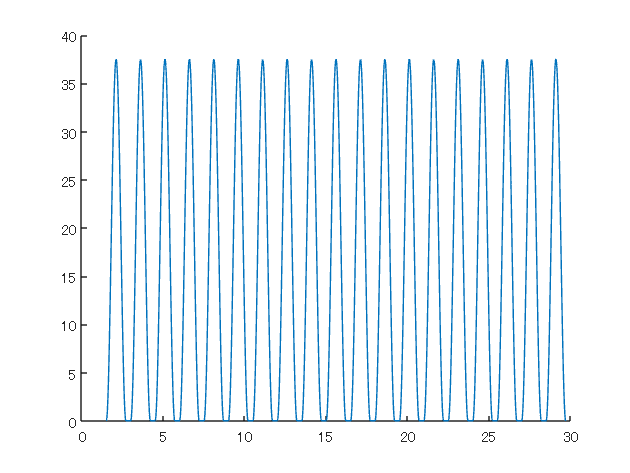

writetable(lifter, csvFolderName + '\' + "lifter.csv");
figure;
[lifter_x, lifter_t] = showGraph(clockTime, deltaTime, absolutePosition);

左ペダル

L = pedalLength; % スライド長 単位 (mm)
startClockTime = 0; % 開始時刻 (s)
clockTimeU = 0; % 単位 (s)
clockTimeD = period*2/10; % 単位 (s)
deltaTimeU = period*2/10; % 単位 (s)
deltaTimeD = period*2/10; % 単位 (s)
positionU = L; % 単位 (mm)
positionD = 0; % 単位 (mm)

clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
tmp = [clockTimeUList; clockTimeDList];
clockTime = tmp(:);
deltaTimeUList = deltaTimeU + 0*clockTimeUList;
deltaTimeDList = deltaTimeD + 0*clockTimeDList;
tmp = [deltaTimeUList; deltaTimeDList];
deltaTime = tmp(:);
positionUList = positionU + 0*clockTimeUList;
positionDList = positionD + 0*clockTimeDList;
tmp = [positionUList; positionDList];
absolutePosition = tmp(:);

% clockTime(end+1) = clockTimeLimit + period/2;
% deltaTime(end+1) = period/2;
% absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

leftPedal = table(clockTime, deltaTime, absolutePosition, useStiffness)

leftPedal = 20×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

         0          0.6              40                0      
       0.6          0.6               0                0      
         3          0.6              40                0      
       3.6          0.6               0                0      
         6          0.6              40                0      
       6.6          0.6               0                0      
         9          0.6              40                0      
       9.6          0.6               0                0      
        12          0.6              40                0      
      12.6          0.6               0                0      
        15          0.6              40                0      
      15.6          0.6               0                0      
        18          0.6              40                0      
      18.6          0.6        

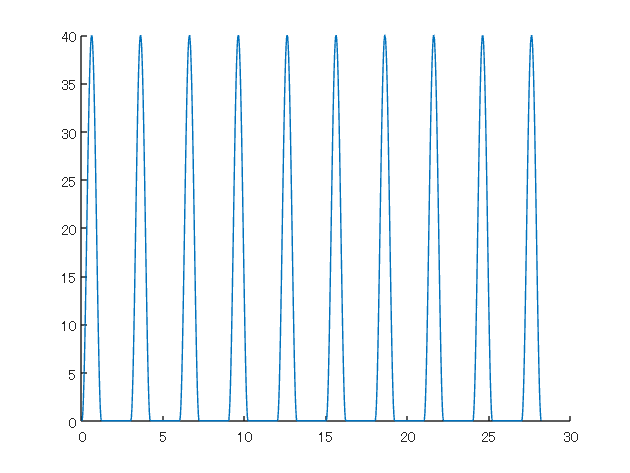

writetable(leftPedal, csvFolderName + '\' + "leftPedal.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[leftPedal_x, leftPedal_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ペダル

L = pedalLength; % スライド長 単位 (mm)
startClockTime = period/2; % 開始時刻 (s) 
clockTimeU = 0; % 単位 (s)
clockTimeD = period*2/10; % 単位 (s)
deltaTimeU = period*2/10; % 単位 (s)
deltaTimeD = period*2/10; % 単位 (s)
positionU = L; % 単位 (mm)
positionD = 0; % 単位 (mm)

clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
tmp = [clockTimeUList; clockTimeDList];
clockTime = tmp(:);
deltaTimeUList = deltaTimeU + 0*clockTimeUList;
deltaTimeDList = deltaTimeD + 0*clockTimeDList;
tmp = [deltaTimeUList; deltaTimeDList];
deltaTime = tmp(:);
positionUList = positionU + 0*clockTimeUList;
positionDList = positionD + 0*clockTimeDList;
tmp = [positionUList; positionDList];
absolutePosition = tmp(:);

% clockTime(end+1) = clockTimeLimit + period/2;
% deltaTime(end+1) = period/2;
% absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

rightPedal = table(clockTime, deltaTime, absolutePosition, useStiffness)

rightPedal = 20×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

       1.5          0.6              40                0      
       2.1          0.6               0                0      
       4.5          0.6              40                0      
       5.1          0.6               0                0      
       7.5          0.6              40                0      
       8.1          0.6               0                0      
      10.5          0.6              40                0      
      11.1          0.6               0                0      
      13.5          0.6              40                0      
      14.1          0.6               0                0      
      16.5          0.6              40                0      
      17.1          0.6               0                0      
      19.5          0.6              40                0      
      20.1          0.6       

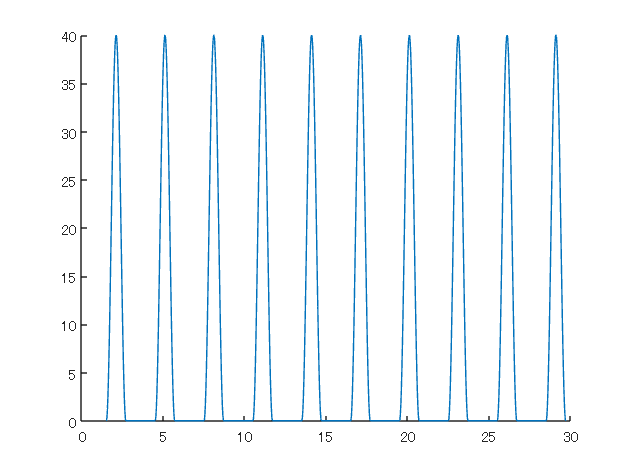

writetable(rightPedal, csvFolderName + '\' + "rightPedal.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[rightPedal_x, rightPedal_t] = showGraph(clockTime, deltaTime, absolutePosition);

椅子　左　スライダ

startClockTime = 0; % 開始時刻 (s)
clockTimeF = 0; % 単位 (s)
clockTimeB = period*4/10; % 単位 (s)
deltaTimeF = period*4/10; % 単位 (s)
deltaTimeB = period*6/10; % 単位 (s)
positionF = seatSlideForwardLength; % 単位 (mm)
positionB = -seatSlideBackwardLength; % 単位 (mm)

clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeFList; clockTimeBList];
clockTime = tmp(:);
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
tmp = [deltaTimeFList; deltaTimeBList];
deltaTime = tmp(:);
positionFList = positionF + 0*clockTimeFList;
positionBList = positionB + 0*clockTimeBList;
tmp = [positionFList; positionBList];
absolutePosition = tmp(:);

% clockTime(end+1) = clockTimeLimit + period/2;
% deltaTime(end+1) = period/2;
% absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

seatLeftSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

seatLeftSlider = 20×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

         0          1.2             100                0      
       1.2          1.8             -50                0      
         3          1.2             100                0      
       4.2          1.8             -50                0      
         6          1.2             100                0      
       7.2          1.8             -50                0      
         9          1.2             100                0      
      10.2          1.8             -50                0      
        12          1.2             100                0      
      13.2          1.8             -50                0      
        15          1.2             100                0      
      16.2          1.8             -50                0      
        18          1.2             100                0      
      19.2          1.8   

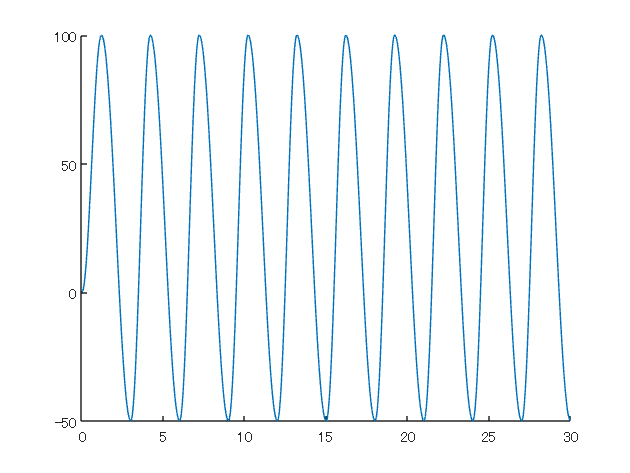

writetable(seatLeftSlider, csvFolderName + '\' + "seatLeftSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[seatLeftSlider_x, seatLeftSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);


clockTimeVibro = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]))' - 0.5;
LeftFootVibro = table(clockTimeVibro)

LeftFootVibro = 10×1 table
    clockTimeVibro
    ______________

          0.7     
          3.7     
          6.7     
          9.7     
         12.7     
         15.7     
         18.7     
         21.7     
         24.7     
         27.7     


writetable(LeftFootVibro, csvFolderName + '\' + "leftFootVibro.csv");

椅子　右　スライダ

startClockTime = period/2; % 開始時刻 (s)
clockTimeF = 0; % 単位 (s)
clockTimeB = period*4/10; % 単位 (s)
deltaTimeF = period*4/10; % 単位 (s)
deltaTimeB = period*6/10; % 単位 (s)
positionF = seatSlideForwardLength; % 単位 (mm)
positionB = -seatSlideBackwardLength; % 単位 (mm)

clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeFList; clockTimeBList];
clockTime = tmp(:);
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
tmp = [deltaTimeFList; deltaTimeBList];
deltaTime = tmp(:);
positionFList = positionF + 0*clockTimeFList;
positionBList = positionB + 0*clockTimeBList;
tmp = [positionFList; positionBList];
absolutePosition = tmp(:);

% clockTime(end+1) = clockTimeLimit + period/2;
% deltaTime(end+1) = period/2;
% absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

seatRightSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

seatRightSlider = 20×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

       1.5          1.2             100                0      
       2.7          1.8             -50                0      
       4.5          1.2             100                0      
       5.7          1.8             -50                0      
       7.5          1.2             100                0      
       8.7          1.8             -50                0      
      10.5          1.2             100                0      
      11.7          1.8             -50                0      
      13.5          1.2             100                0      
      14.7          1.8             -50                0      
      16.5          1.2             100                0      
      17.7          1.8             -50                0      
      19.5          1.2             100                0      
      20.7          1.8  

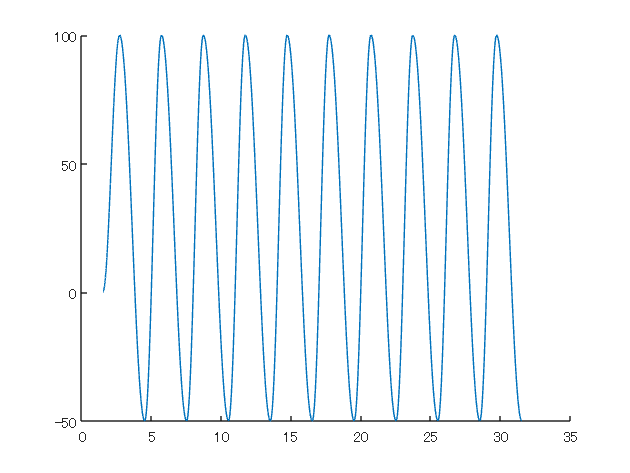

writetable(seatRightSlider, csvFolderName + '\' + "seatRightSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[seatRightSlider_x, seatRightSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

clockTimeVibro = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]))' - 0.5;
RightFootVibro = table(clockTimeVibro)

RightFootVibro = 10×1 table
    clockTimeVibro
    ______________

          2.2     
          5.2     
          8.2     
         11.2     
         14.2     
         17.2     
         20.2     
         23.2     
         26.2     
         29.2     


writetable(RightFootVibro, csvFolderName + '\' + "rightFootVibro.csv");

左ストックの伸縮　登山

L = extendLength; % スライド長 単位 (mm)
startClockTime = period*1/10; % 開始時刻 (s)
clockTimeU = 0; % 単位 (s)
clockTimeD = period*2/10; % 単位 (s)
deltaTimeU = period*2/10; % 単位 (s)
deltaTimeD = period*2/10; % 単位 (s)
positionU = L; % 単位 (mm)
positionD = 0; % 単位 (mm)

clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
tmp = [clockTimeUList; clockTimeDList];
clockTime = tmp(:);
deltaTimeUList = deltaTimeU + 0*clockTimeUList;
deltaTimeDList = deltaTimeD + 0*clockTimeDList;
tmp = [deltaTimeUList; deltaTimeDList];
deltaTime = tmp(:);
positionUList = positionU + 0*clockTimeUList;
positionDList = positionD + 0*clockTimeDList;
tmp = [positionUList; positionDList];
absolutePosition = tmp(:);
tmp = [zeros(size(clockTimeUList)); ones(size(clockTimeDList))];
useStiffness = tmp(:);

% clockTime(end+1) = clockTimeLimit + period/2;
% deltaTime(end+1) = period/2;
% absolutePosition(end+1) = 0;
% useStiffness(end+1) = 0;

stockLeftExtend = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockLeftExtend = 20×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

       0.3          0.6             125                0      
       0.9          0.6               0                1      
       3.3          0.6             125                0      
       3.9          0.6               0                1      
       6.3          0.6             125                0      
       6.9          0.6               0                1      
       9.3          0.6             125                0      
       9.9          0.6               0                1      
      12.3          0.6             125                0      
      12.9          0.6               0                1      
      15.3          0.6             125                0      
      15.9          0.6               0                1      
      18.3          0.6             125                0      
      18.9          0.6  

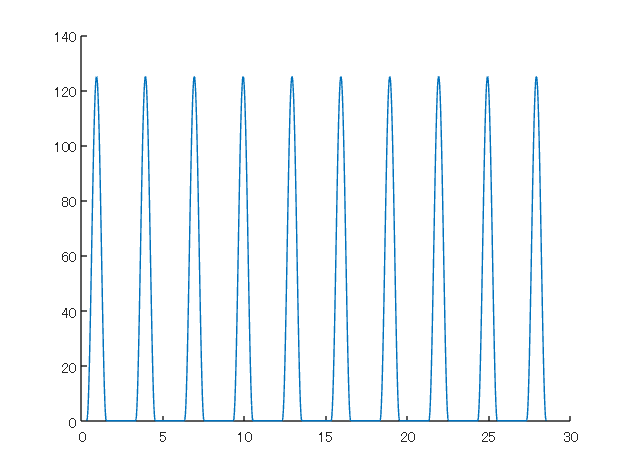

writetable(stockLeftExtend, csvFolderName + '\' + "stockLeftExtend.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[stockLeftExtend_x, stockLeftExtend_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストックの伸縮　登山


L = extendLength; % スライド長 単位 (mm)
startClockTime = period*6/10; % 開始時刻 (s)
clockTimeU = 0; % 単位 (s)
clockTimeD = period*2/10; % 単位 (s)
deltaTimeU = period*2/10; % 単位 (s)
deltaTimeD = period*2/10; % 単位 (s)
positionU = L; % 単位 (mm)
positionD = 0; % 単位 (mm)

clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
tmp = [clockTimeUList; clockTimeDList];
clockTime = tmp(:);
deltaTimeUList = deltaTimeU + 0*clockTimeUList;
deltaTimeDList = deltaTimeD + 0*clockTimeDList;
tmp = [deltaTimeUList; deltaTimeDList];
deltaTime = tmp(:);
positionUList = positionU + 0*clockTimeUList;
positionDList = positionD + 0*clockTimeDList;
tmp = [positionUList; positionDList];
absolutePosition = tmp(:);
tmp = [zeros(size(clockTimeUList)); ones(size(clockTimeDList))];
useStiffness = tmp(:);

% clockTime(end+1) = clockTimeLimit + period/2;
% deltaTime(end+1) = period/2;
% absolutePosition(end+1) = 0;
% useStiffness(end+1) = 0;

stockRightExtend = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockRightExtend = 20×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

       1.8          0.6             125                0      
       2.4          0.6               0                1      
       4.8          0.6             125                0      
       5.4          0.6               0                1      
       7.8          0.6             125                0      
       8.4          0.6               0                1      
      10.8          0.6             125                0      
      11.4          0.6               0                1      
      13.8          0.6             125                0      
      14.4          0.6               0                1      
      16.8          0.6             125                0      
      17.4          0.6               0                1      
      19.8          0.6             125                0      
      20.4          0.6 

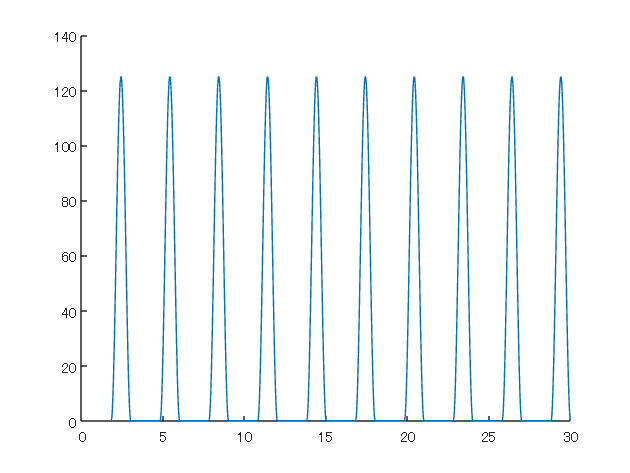

writetable(stockRightExtend, csvFolderName + '\' + "stockRightExtend.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[stockRightExtend_x, stockRightExtend_t] = showGraph(clockTime, deltaTime, absolutePosition);

左ストックのスライダ

startClockTime = period*1/10; % 開始時刻 (s)
clockTimeF = 0; % 単位 (s)
clockTimeB = period*4/10; % 単位 (s)
deltaTimeF = period*4/10; % 単位 (s)
deltaTimeB = period*6/10; % 単位 (s)
positionF = stockSlideForwardLength; % 単位 (mm)
positionB = -stockSlideBackwardLength; % 単位 (mm)

clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeFList; clockTimeBList];
clockTime = tmp(:);
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
tmp = [deltaTimeFList; deltaTimeBList];
deltaTime = tmp(:);
positionFList = positionF + 0*clockTimeFList;
positionBList = positionB + 0*clockTimeBList;
tmp = [positionFList; positionBList];
absolutePosition = tmp(:);

% clockTime(end+1) = clockTimeLimit + period/2;
% deltaTime(end+1) = period/2;
% absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

stockLeftSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockLeftSlider = 20×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

       0.3          1.2            187.5               0      
       1.5          1.8             -125               0      
       3.3          1.2            187.5               0      
       4.5          1.8             -125               0      
       6.3          1.2            187.5               0      
       7.5          1.8             -125               0      
       9.3          1.2            187.5               0      
      10.5          1.8             -125               0      
      12.3          1.2            187.5               0      
      13.5          1.8             -125               0      
      15.3          1.2            187.5               0      
      16.5          1.8             -125               0      
      18.3          1.2            187.5               0      
      19.5          1.8  

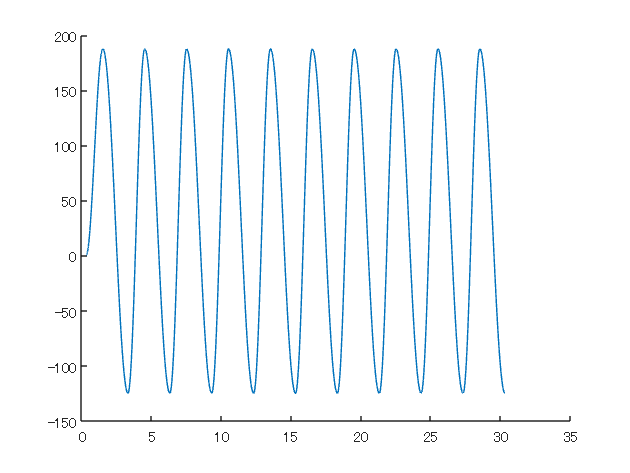

writetable(stockLeftSlider, csvFolderName + '\' + "stockLeftSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[stockLeftSlider_x, stockLeftSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストックのスライダ


L = stockSlideForwardLength; % スライド長 単位 (mm)
startClockTime = period*6/10; % 開始時刻 (s)
clockTimeF = 0; % 単位 (s)
clockTimeB = period*4/10; % 単位 (s)
deltaTimeF = period*4/10; % 単位 (s)
deltaTimeB = period*6/10; % 単位 (s)
positionF = stockSlideForwardLength; % 単位 (mm)
positionB = -stockSlideBackwardLength; % 単位 (mm)

clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeFList; clockTimeBList];
clockTime = tmp(:);
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
tmp = [deltaTimeFList; deltaTimeBList];
deltaTime = tmp(:);
positionFList = positionF + 0*clockTimeFList;
positionBList = positionB + 0*clockTimeBList;
tmp = [positionFList; positionBList];
absolutePosition = tmp(:);

% clockTime(end+1) = clockTimeLimit + period/2;
% deltaTime(end+1) = period/2;
% absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

stockRightSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockRightSlider = 20×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

       1.8          1.2            187.5               0      
         3          1.8             -125               0      
       4.8          1.2            187.5               0      
         6          1.8             -125               0      
       7.8          1.2            187.5               0      
         9          1.8             -125               0      
      10.8          1.2            187.5               0      
        12          1.8             -125               0      
      13.8          1.2            187.5               0      
        15          1.8             -125               0      
      16.8          1.2            187.5               0      
        18          1.8             -125               0      
      19.8          1.2            187.5               0      
        21          1.8 

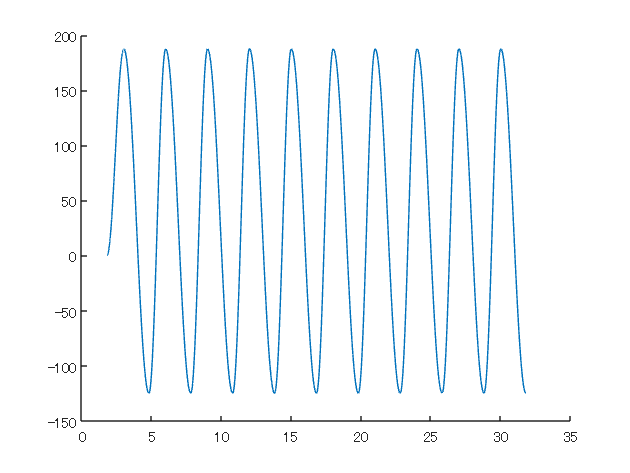

writetable(stockRightSlider, csvFolderName + '\' + "stockRightSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[stockRightSlider_x, stockRightSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

左ストック 前後傾

LF = tiltForwardDeg; % 単位 (deg)
LB = tiltBackwardDeg; % 単位 (deg)
startClockTimeLeftTilt = 0; % 開始時刻 (s)
clockTimeB = 0; % 単位 (s)
clockTimeF = period*4/10; % 単位 (s)
leftTiltDeltaTimeB = period*4/10; % 単位 (s)
leftTiltDeltaTimeF = period*6/10; % 単位 (s)
% leftTiltDelayTimeB = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) - leftTiltDeltaTimeF;
leftTiltDelayTimeB = 0;
leftTiltDelayTimeF = 0;
positionB = LB; % 単位 (deg)
positionF = LF; % 単位 (deg)

clockTimeBList = (startClockTimeLeftTilt + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = (startClockTimeLeftTilt + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeBList; clockTimeFList];
clockTime = tmp(:);
deltaTimeBList = leftTiltDeltaTimeB + 0*clockTimeBList;
deltaTimeFList = leftTiltDeltaTimeF + 0*clockTimeFList;
tmp = [deltaTimeBList; deltaTimeFList];
deltaTime = tmp(:);
positionBList = positionB + 0*clockTimeBList;
positionFList = positionF + 0*clockTimeFList;
tmp = [positionBList; positionFList];
absolutePosition = tmp(:);

% clockTime(end+1) = clockTimeLimit + period/2;
% deltaTime(end+1) = period/2;
% absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

leftTilt = table(clockTime, deltaTime, absolutePosition, useStiffness)

leftTilt = 20×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

         0          1.2                5               0      
       1.2          1.8            -12.5               0      
         3          1.2                5               0      
       4.2          1.8            -12.5               0      
         6          1.2                5               0      
       7.2          1.8            -12.5               0      
         9          1.2                5               0      
      10.2          1.8            -12.5               0      
        12          1.2                5               0      
      13.2          1.8            -12.5               0      
        15          1.2                5               0      
      16.2          1.8            -12.5               0      
        18          1.2                5               0      
      19.2          1.8         

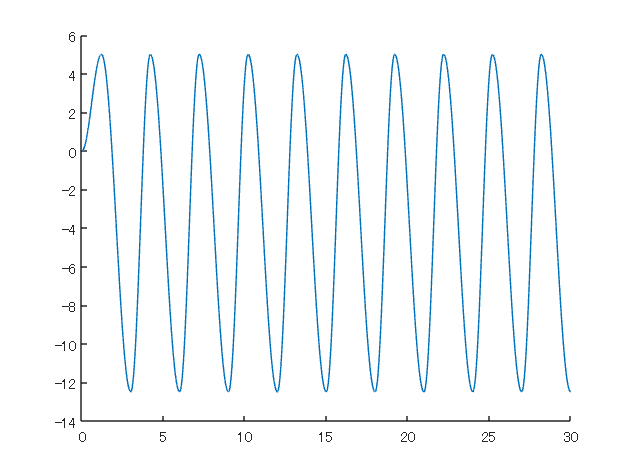

writetable(leftTilt, csvFolderName + '\' + "leftTilt.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[leftTilt_x, leftTilt_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストック 前後傾

LF = tiltForwardDeg; % 単位 (deg)
LB = tiltBackwardDeg; % 単位 (deg)
startClockTimeRightTilt = period/2; % 開始時刻 (s)
clockTimeB = 0; % 単位 (s)
clockTimeF = period*4/10; % 単位 (s)
rightTiltDeltaTimeB = period*4/10; % 単位 (s)
rightTiltDeltaTimeF = period*6/10; % 単位 (s)
% rightTiltDelayTimeB = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) - rightTiltDeltaTimeF;
rightTiltDelayTimeB = 0;
rightTiltDelayTimeF = 0;
positionB = LB; % 単位 (deg)
positionF = LF; % 単位 (deg)

clockTimeBList = (startClockTimeRightTilt + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = (startClockTimeRightTilt + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeBList; clockTimeFList];
clockTime = tmp(:);
deltaTimeBList = rightTiltDeltaTimeB + 0*clockTimeBList;
deltaTimeFList = rightTiltDeltaTimeF + 0*clockTimeFList;
tmp = [deltaTimeBList; deltaTimeFList];
deltaTime = tmp(:);
positionBList = positionB + 0*clockTimeBList;
positionFList = positionF + 0*clockTimeFList;
tmp = [positionBList; positionFList];
absolutePosition = tmp(:);

% clockTime(end+1) = clockTimeLimit + period/2;
% deltaTime(end+1) = period/2;
% absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

rightTilt = table(clockTime, deltaTime, absolutePosition, useStiffness)

rightTilt = 20×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

       1.5          1.2                5               0      
       2.7          1.8            -12.5               0      
       4.5          1.2                5               0      
       5.7          1.8            -12.5               0      
       7.5          1.2                5               0      
       8.7          1.8            -12.5               0      
      10.5          1.2                5               0      
      11.7          1.8            -12.5               0      
      13.5          1.2                5               0      
      14.7          1.8            -12.5               0      
      16.5          1.2                5               0      
      17.7          1.8            -12.5               0      
      19.5          1.2                5               0      
      20.7          1.8        

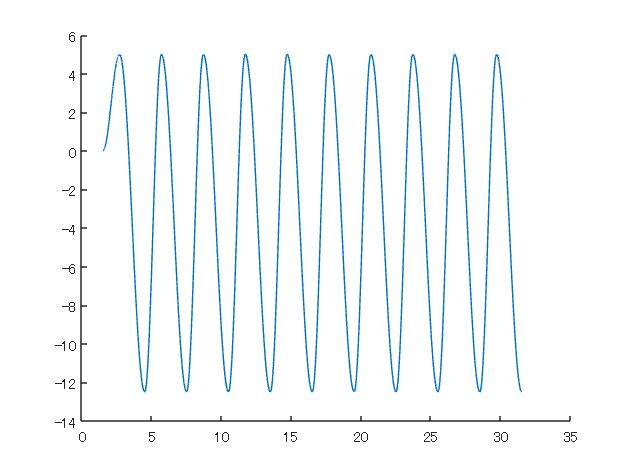

writetable(rightTilt, csvFolderName + '\' + "rightTilt.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[rightTilt_x, rightTilt_t] = showGraph(clockTime, deltaTime, absolutePosition);

TiltCSV = table( ...
    period, tiltBackwardDeg, tiltForwardDeg, tiltBackwardTimeRate, tiltForwardTimeRate, startClockTimeLeftTilt, startClockTimeRightTilt, ...
    leftTiltDeltaTimeB, leftTiltDeltaTimeF, rightTiltDeltaTimeB, rightTiltDeltaTimeF, ...
    leftTiltDelayTimeB, leftTiltDelayTimeF, rightTiltDelayTimeB, rightTiltDelayTimeF ...
    )

TiltCSV = 1×15 table
    period    tiltBackwardDeg    tiltForwardDeg    tiltBackwardTimeRate    tiltForwardTimeRate    startClockTimeLeftTilt    startClockTimeRightTilt    leftTiltDeltaTimeB    leftTiltDeltaTimeF    rightTiltDeltaTimeB    rightTiltDeltaTimeF    leftTiltDelayTimeB    leftTiltDelayTimeF    rightTiltDelayTimeB    rightTiltDelayTimeF
    ______    _______________    ______________    ____________________    ___________________    ______________________    _______________________    __________________    __________________    ___________________    ___________________    __________________    __________________    ___________________    ___________________

      3              5               -12.5                  4                       6                       0                         1.5                     1.2                   1.8                    1.2                    1.8                    0                     0                      0                      0    

writetable(TiltCSV, csvFolderName + '\' + 'tilt.csv');

signal_lifter = timeseries(lifter_x, lifter_t, Name='lifter');
signal_leftPedal = timeseries(leftPedal_x, leftPedal_t, Name='leftPedal');
signal_rightPedal = timeseries(rightPedal_x, rightPedal_t, Name='rightPedal');
signal_seatLeftSlider = timeseries(seatLeftSlider_x, seatLeftSlider_t, Name='seatLeftSlider');
signal_seatRightSlider = timeseries(seatRightSlider_x, seatRightSlider_t, Name='seatRightSlider');
signal_stockLeftSlider = timeseries(stockLeftSlider_x, stockLeftSlider_t, Name='stockLeftSlider');
signal_stockRightSlider = timeseries(stockRightSlider_x, stockRightSlider_t, Name='stockRightSlider');
signal_stockLeftExtend = timeseries(stockLeftExtend_x, stockLeftExtend_t, Name='stockLeftExtend');
signal_stockRightExtend = timeseries(stockRightExtend_x, stockRightExtend_t, Name='stockRightExtend');
signal_leftTilt = timeseries(leftTilt_x, leftTilt_t, Name="leftTilt");
signal_rightTilt = timeseries(rightTilt_x, rightTilt_t, Name="rightTilt");

Scenario = Simulink.SimulationData.Dataset;

Scenario{1} = signal_lifter;
Scenario{2} = signal_leftPedal;
Scenario{3} = signal_rightPedal;
Scenario{4} = signal_seatLeftSlider;
Scenario{5} = signal_seatRightSlider;
Scenario{6} = signal_stockLeftExtend;
Scenario{7} = signal_stockRightExtend;
Scenario{8} = signal_stockLeftSlider;
Scenario{9} = signal_stockRightSlider;
Scenario{10} = signal_leftTilt;
Scenario{11} = signal_rightTilt;


% Scenario{2} = SignalStickRightPitch;
% Scenario{2}.Name = 'SignalStickRightPitch';
% Scenario{5} = signal_stockLeftPitch;
% Scenario{5}.Name = 'SignalStickLeftPitch';

save('../../../scenario.mat', 'Scenario');

sim("Simulink.slx");

clear;

function showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
    t = 0:0.001:deltaTime(1);
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    plot(t + clockTime(1), x);
    hold on;
    for idx = 2:length(clockTime)
        t = 0:0.01:deltaTime(idx);
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        plot(t + clockTime(idx), x);
    end
end

function [ret_x, ret_t] = showGraph(clockTime, deltaTime, absolutePosition)
    % ret_t = [];
    t = (0:0.001:deltaTime(1))';
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    % plot(t + clockTime(1), x);
    ret_x = x;
    ret_t = t + clockTime(1);
    hold on;
    for idx = 2:length(clockTime)
        t = (0:0.01:deltaTime(idx))';
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        % plot(t + clockTime(idx), x);
        ret_t = [ret_t; t + clockTime(idx)];
        ret_x = [ret_x; x];
    end
    plot(ret_t, ret_x);
end
